% Load data from the new URL
url = 'https://raw.githubusercontent.com/Alex-Varghese/MATLAB/refs/heads/main/heart_2020_cleaned.csv';
opts = detectImportOptions(url);
df = readtable(url, opts);

% Rename the target column (adjust if target column name is known)
df.Properties.VariableNames{strcmp(df.Properties.VariableNames, 'HeartDisease')} = 'target';

% Ensure all predictors are numeric
X = removevars(df, 'target'); % Features
categorical_vars = varfun(@iscategorical, X, 'OutputFormat', 'uniform');
string_vars = varfun(@isstring, X, 'OutputFormat', 'uniform');
cell_vars = varfun(@iscell, X, 'OutputFormat', 'uniform'); % Identify cell array columns

% Convert categorical, string, and cell variables to numerical encoding
for i = find(categorical_vars | string_vars | cell_vars)
    if cell_vars(i)
        % Convert cell arrays to categorical first, then to double
        X.(i) = double(categorical(X.(i)));
    else
        % Convert directly to numerical
        X.(i) = double(categorical(X.(i)));
    end
end

% Convert the table to numeric format if necessary
X = varfun(@double, X);

% Process the target variable (binary or categorical encoding)
if iscell(df.target) || iscategorical(df.target)
    target_categories = categories(categorical(df.target));
    df.target = double(categorical(df.target)) - 1; % Encode as 0, 1, 2, ...
end
y = df.target; % Target variable

% Split data into training and testing sets
cv = cvpartition(height(df), 'HoldOut', 0.2);
X_train = X(training(cv), :);
y_train = y(training(cv), :);
X_test = X(test(cv), :);
y_test = y(test(cv), :);

% Decision Tree Regression
dt = fitrtree(X_train, y_train);

% Random Forest Regression
rf = fitrensemble(X_train, y_train, 'Method', 'Bag', 'NumLearningCycles', 100);

% Predictions
y_train_pred_dt = predict(dt, X_train);
y_test_pred_dt = predict(dt, X_test);

y_train_pred_rf = predict(rf, X_train);
y_test_pred_rf = predict(rf, X_test);

% Calculate Mean Squared Error and R2 for Decision Tree
train_mse_dt = mean((y_train - y_train_pred_dt).^2);
train_r2_dt = 1 - sum((y_train - y_train_pred_dt).^2) / sum((y_train - mean(y_train)).^2);
test_mse_dt = mean((y_test - y_test_pred_dt).^2);
test_r2_dt = 1 - sum((y_test - y_test_pred_dt).^2) / sum((y_test - mean(y_test)).^2);

% Calculate Mean Squared Error and R2 for Random Forest
train_mse_rf = mean((y_train - y_train_pred_rf).^2);
train_r2_rf = 1 - sum((y_train - y_train_pred_rf).^2) / sum((y_train - mean(y_train)).^2);
test_mse_rf = mean((y_test - y_test_pred_rf).^2);
test_r2_rf = 1 - sum((y_test - y_test_pred_rf).^2) / sum((y_test - mean(y_test)).^2);

% Display results
disp(['Decision Tree Mean Squared Error (Train): ', num2str(train_mse_dt)]);

Decision Tree Mean Squared Error (Train): 0.032054


disp(['Decision Tree R2 (Train): ', num2str(train_r2_dt)]);

Decision Tree R2 (Train): 0.58958


disp(['Decision Tree Mean Squared Error (Test): ', num2str(test_mse_dt)]);

Decision Tree Mean Squared Error (Test): 0.1039


disp(['Decision Tree R2 (Test): ', num2str(test_r2_dt)]);

Decision Tree R2 (Test): -0.31607



disp(['Random Forest Mean Squared Error (Train): ', num2str(train_mse_rf)]);

Random Forest Mean Squared Error (Train): 0.046659


disp(['Random Forest R2 (Train): ', num2str(train_r2_rf)]);

Random Forest R2 (Train): 0.40257


disp(['Random Forest Mean Squared Error (Test): ', num2str(test_mse_rf)]);

Random Forest Mean Squared Error (Test): 0.068206


disp(['Random Forest R2 (Test): ', num2str(test_r2_rf)]);

Random Forest R2 (Test): 0.13606


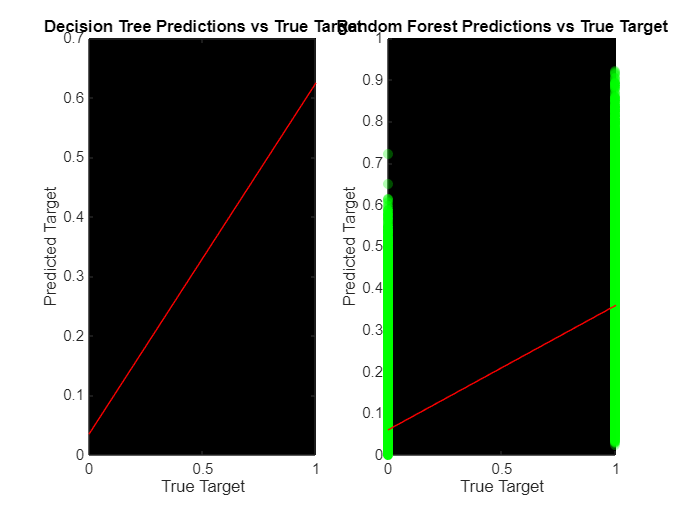


% Plot predictions vs actual for Decision Tree
figure;
subplot(1, 2, 1);
scatter(y_train, y_train_pred_dt, 'filled', 'MarkerFaceColor', 'b', 'MarkerEdgeColor', 'none', 'MarkerFaceAlpha', 0.3); % Blue hold on;
p_dt = polyfit(y_train, y_train_pred_dt, 1);
yfit_dt = polyval(p_dt, y_train);
plot(y_train, yfit_dt, 'r'); % Red
xlabel('True Target');
ylabel('Predicted Target');
title('Decision Tree Predictions vs True Target');
set(gca, 'Color', 'k'); % Black background

% Plot predictions vs actual for Random Forest
subplot(1, 2, 2);
scatter(y_train, y_train_pred_rf, 'filled', 'MarkerFaceColor', 'g', 'MarkerEdgeColor', 'none', 'MarkerFaceAlpha', 0.3); % Green
hold on;
p_rf = polyfit(y_train, y_train_pred_rf, 1);
yfit_rf = polyval(p_rf, y_train);
plot(y_train, yfit_rf, 'r'); % Red
xlabel('True Target');
ylabel('Predicted Target');
title('Random Forest Predictions vs True Target');
set(gca, 'Color', 'k'); % Black background


% Prediction for new input data
input_data = [22.59,1,0,0,0,30,1,70-74,0.5,1,5,8,0,0,0]; % Example with 15 features
input_data_reshaped = reshape(input_data, 1, []);
numeric_prediction_dt = predict(dt, input_data_reshaped);
numeric_prediction_rf = predict(rf, input_data_reshaped);

% Map numerical prediction to categories for Decision Tree
if exist('target_categories', 'var')
    risk_levels = target_categories; % Use categories from encoding step
    predicted_risk_dt = risk_levels{round(numeric_prediction_dt) + 1};
    disp(['Decision Tree: The risk level for the patient is: ', predicted_risk_dt, '.']);
else
    disp(['Decision Tree: Predicted target value: ', num2str(numeric_prediction_dt)]);
end

Decision Tree: The risk level for the patient is: No.



% Map numerical prediction to categories for Random Forest
if exist('target_categories', 'var')
    predicted_risk_rf = risk_levels{round(numeric_prediction_rf) + 1};
    disp(['Random Forest: The risk level for the patient is: ', predicted_risk_rf, '.']);
else
    disp(['Random Forest: Predicted target value: ', num2str(numeric_prediction_rf)]);
end

Random Forest: The risk level for the patient is: No.
